Problem 1:

t = -5:0.01:10;
x = t.*heaviside(t+5) - t.*heaviside(t+3) - t.*heaviside(t+2) + t.*heaviside(t) + heaviside(t) + heaviside(t-2) + heaviside(t-5) - 3*heaviside(t-8);
plot(t,x)
title("prolbem 1");
hold off;

Problem 3:

x(t) = cos(2*pi*t) + sin(3*pi*t)  - plot;

TODO: Plot for 4 periods

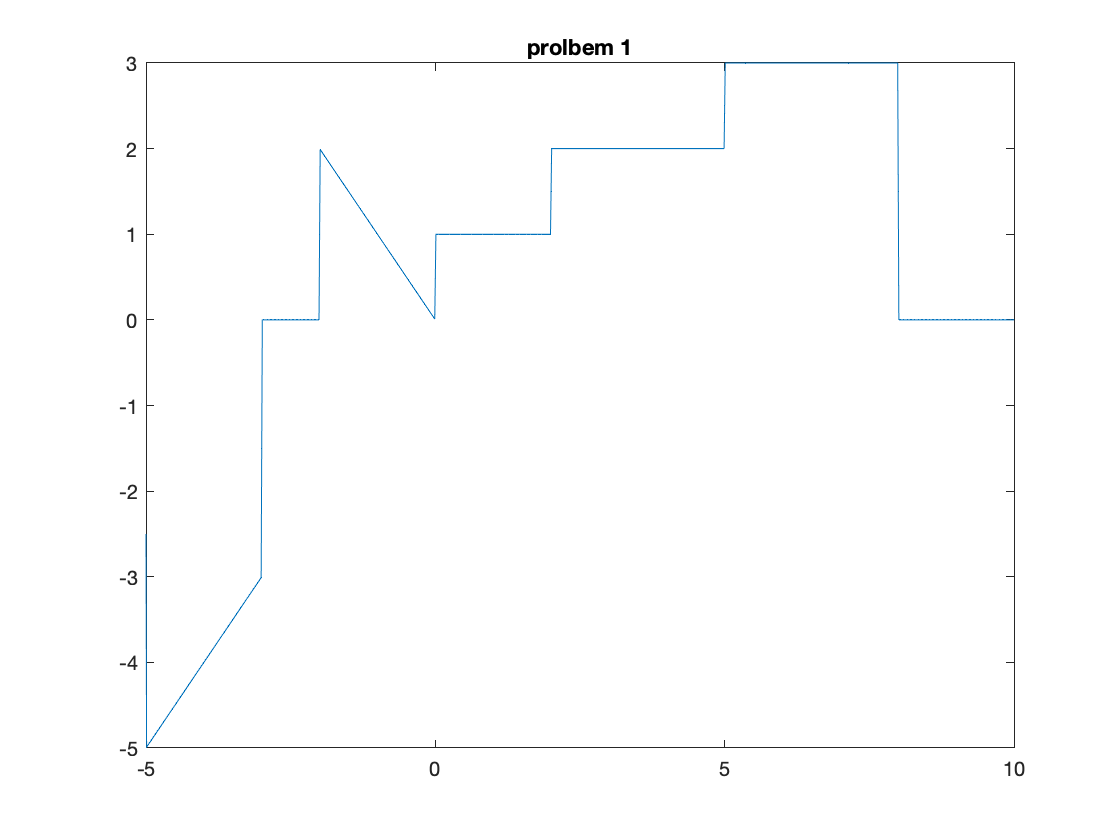

t = [0:0.01:15];
x = cos(2*pi*t) + sin(3*pi*t);

plot(t,x)
title('problem 3 - x(t)=cos(2tPI)+sin(3tPI)');
hold off

Problem 6: - see example problem 10 in text

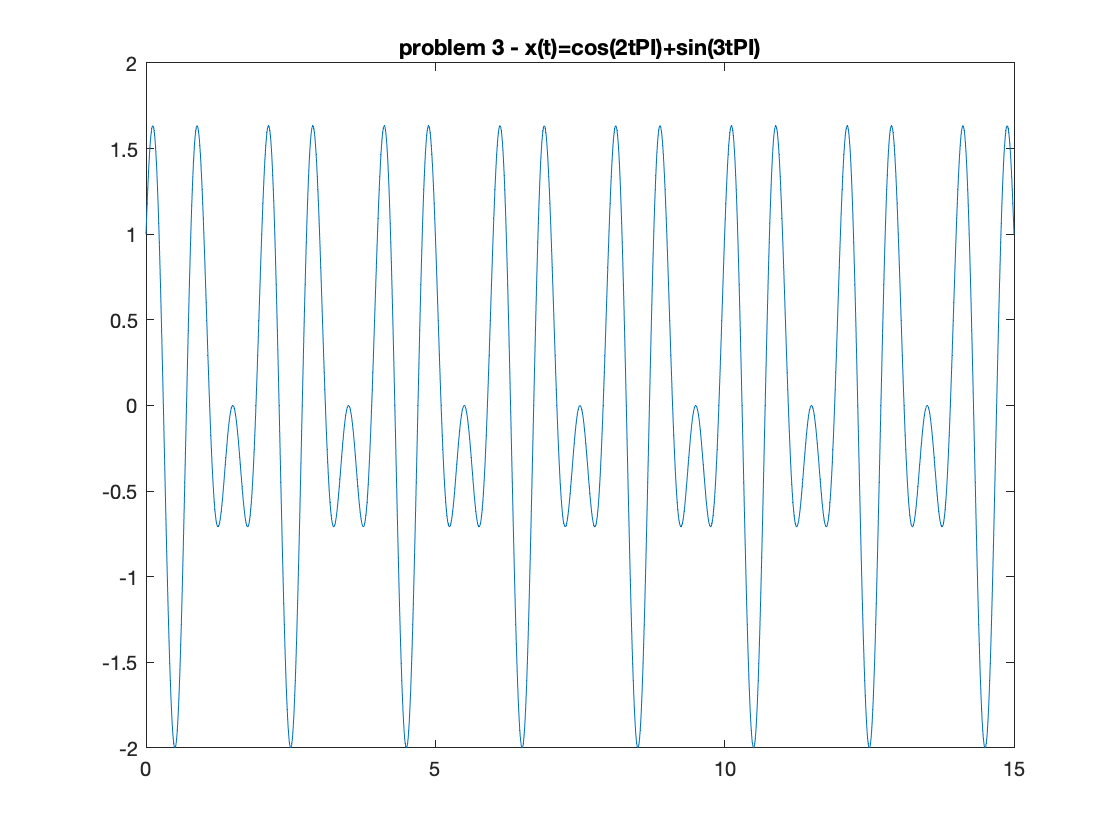

t1 = 0:0.1:2;
t2 = 2:0.1:4;
x_1 = t1;
x_2 = 2*t2-4;
t = [t1 t2];

x = [x_1,x_2];
x_1_half = x_1/2;
x_2_half = x_2/2;
x_half = [x_1_half,x_2_half];
x_shifted_scaled_1 = 2*x_1+4;
x_shifted_scaled_2 = 2*x_2+4;
x_shifted_scaled = [x_shifted_scaled_1,x_shifted_scaled_2];
plot(t,x)
hold on
plot(t,-x)
plot(t,x_half)
plot(t,x_shifted_scaled)
plot(t,-x_shifted_scaled)
title("problem 6")
legend('x','-x','x/2','2x+4','-2x-4')
hold off

Problem 7: Function(t0): return u(t-t0). Graph. 

unit_plotter(5)

Problem 12:  - this one is wrong

ramp_plotter(5)

Problem 16: finish

f(r,w,n) = (r^n)*e^(j*n*w)

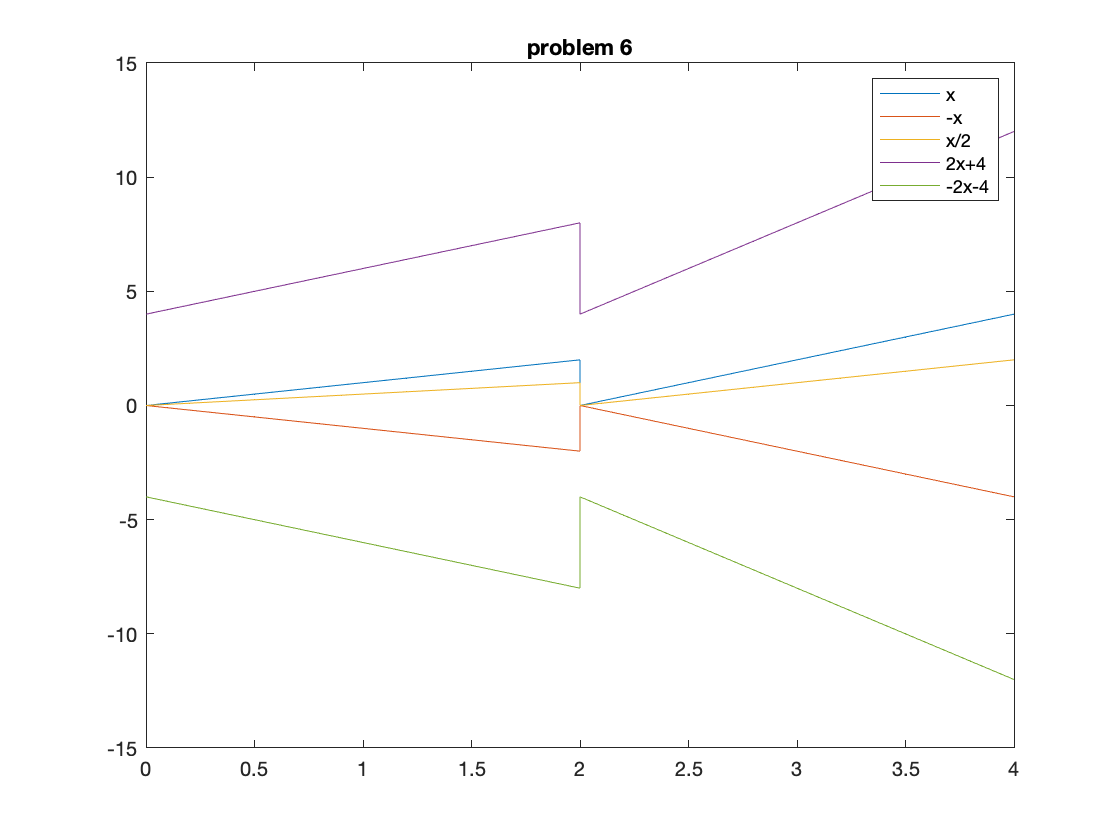

% r = -3:0.01:10;
% w = linspace(0,2*pi,length(r)); 
% n = -3:0.01:10;
% 

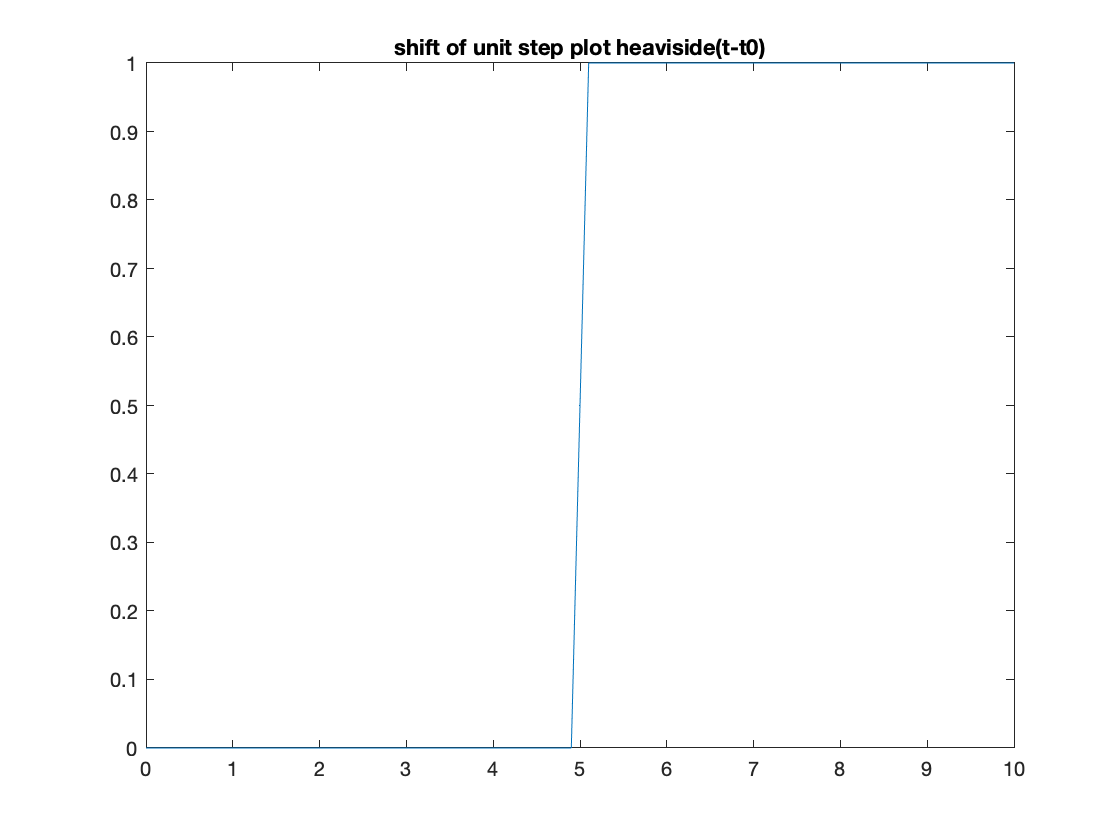

% x_re = real((r.^n).*exp(j*w.*n));
% x_imag = imag((r.^n).*exp(j*w.*n));

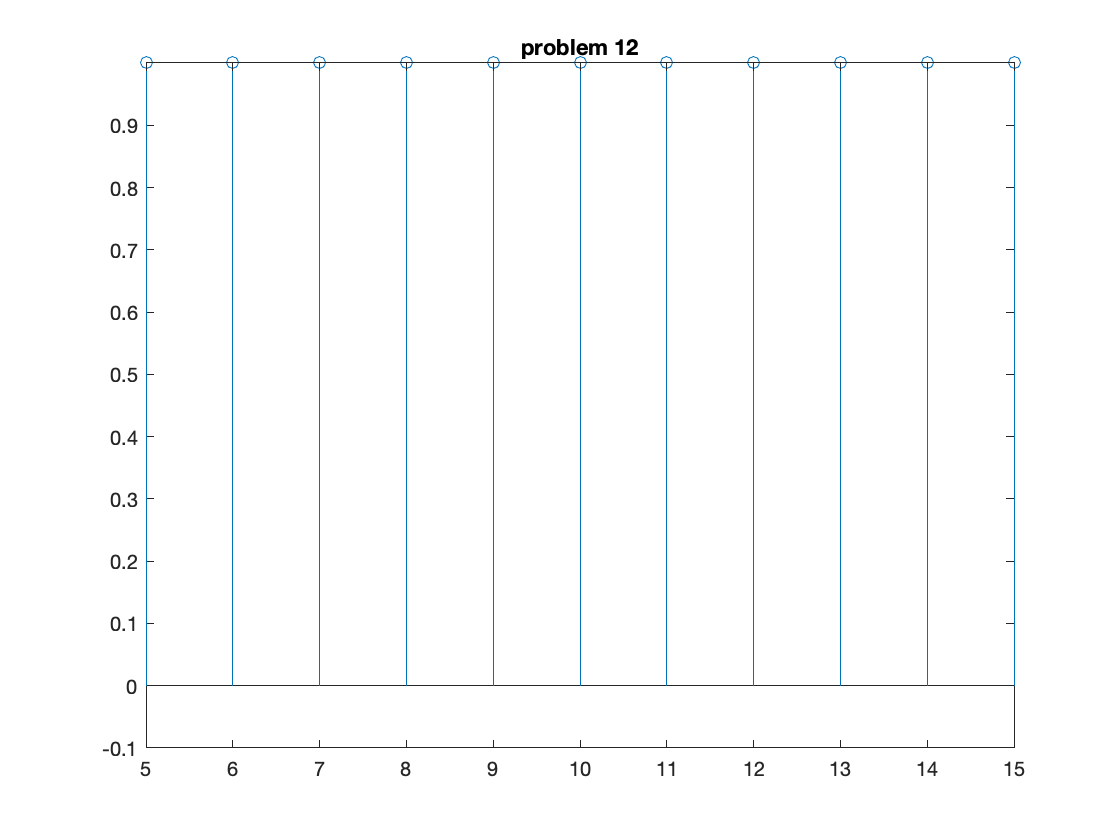

% x_mag = abs((r.^n).*exp(j*w.*n));
% plot(r,x_re,r,x_imag,r,x_mag)

% title('problem 16');
% hold off

problem 16:

plot_many(10,10,[0 2*pi])

Function for problem 7:

function unit_plot = unit_plotter(t_naught)
    start = t_naught-5;
    stop = t_naught+5;
    t = start:0.1:stop;
    x = heaviside(t-t_naught);
    plot(t,x)
    hold on 
    title('shift of unit step plot heaviside(t-t0)')
    hold off
end

function for problem 12:

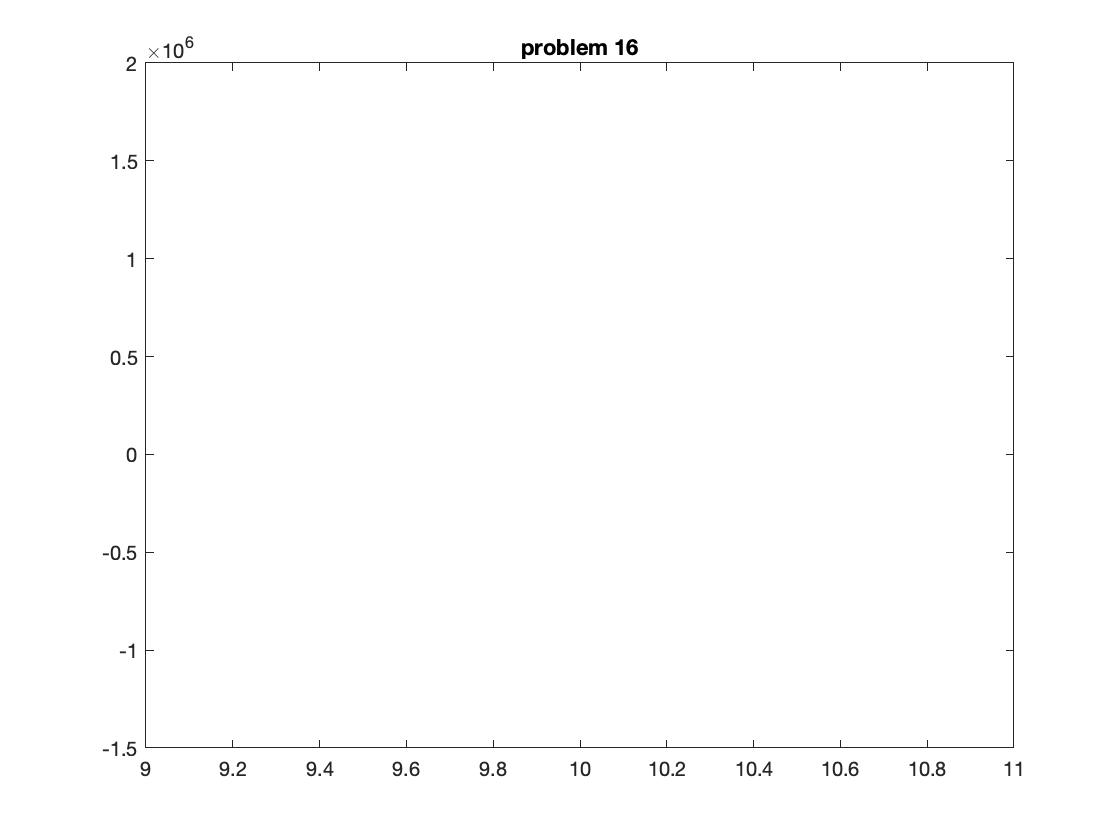

function unit_ramp = ramp_plotter(n_naught)

    start = n_naught-5;
    stop = n_naught + 5;
    n = start:stop;
    u = (n>=0);
    r = (n+n_naught).*u;
    stem(r, u)
    hold on
    title('problem 12');
    ylim([-0.1 inf])
    hold off
end

Function for problem 16: 

function various_plots = plot_many(r, w, n)
    n_ = n(1):0.1:n(2);
    x_re = real((r.^n_).*exp(1i*w.*n_));
    x_imag = imag((r.^n_).*exp(1i*w.*n_));
    x_mag = abs((r.^n_).*exp(1i*w.*n_));
    x_phase = angle((r.^n_).*exp(1i*w.*n_)); 
    plot(r,x_re,r,x_imag,r,x_mag,r,x_phase)
    hold on
    xlim auto
    ylim auto
    title('problem 16')
    hold off

end